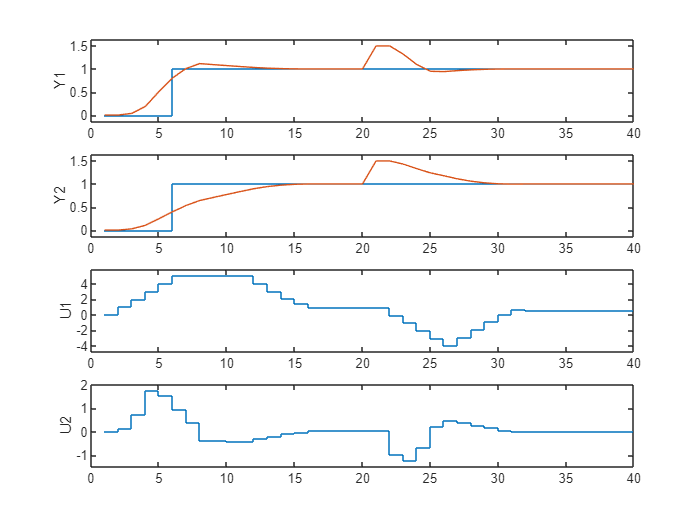

clear

% create a MIMO plant' state space function
ts = 0.01;
numerators = {1 5;1 2};
denominator = {[0.7 1] [0.3 1]; [0.5 1] [0.4 1]};
Gm = tf(numerators,denominator);
Gz = c2d(Gm,ts);
Gz =ss(Gz);
Ap = Gz.A;  % nx * nx
Bp = Gz.B;  % nx * m
Cp = Gz.C;  % p * nx
Dp = Gz.D;  % p * m

% set simulation parameter
tsim = 40;
tstep = 5;
tdis = 20;

% each column is the setpoint or disturbance of a time step
SetPt = [zeros(size(Cp,1),tstep) ones(size(Cp,1),tsim-tstep)];       
dist = [zeros(size(Cp,1),tdis) 0.5*ones(size(Cp,1),tsim-tdis)];    

% set MPC parameters
N1=2;
N2=4;
Nu=2;
Lambda=0;

% whether use CVX to search optimal solution
useCVX = true;

% Set constraint here, unachievable constraints will lead to abnormal results
Ymax = [2;2];Ymin = [0;0];
Umax = [5;5];Umin = [-5;-5];
dUmax = [1;1]; dUmin = [-1;-1];
constraint = {Ymax,Ymin,Umax,Umin,dUmax,dUmin};
% constraint = false;

% Infer the simulation outcome of using a MPC with integral action
[y_plot,u_plot,w_plot] = Infer(Ap,Bp,Cp,N1,N2,Nu,Lambda,SetPt,dist,useCVX,constraint);

% plot result
subplot(411),stairs(w_plot(1,1:tsim)),
hold on,plot(y_plot(1,1:tsim)),ylabel('Y1'),ylim(AdaptiveAxis(y_plot(1,:))),hold off
subplot(412),stairs(w_plot(2,1:tsim)),
hold on,plot(y_plot(2,1:tsim)),ylabel('Y2'),ylim(AdaptiveAxis(y_plot(2,:))),hold off
subplot(413),stairs(u_plot(1,1:tsim)),ylabel('U1'),ylim(AdaptiveAxis(u_plot(1,:)))
subplot(414),stairs(u_plot(2,1:tsim)),ylabel('U2'),ylim(AdaptiveAxis(u_plot(2,:)))

Infer the simulation outcome of using a MPC can handle both SISO and MIMO plant

The MPC with state space model given by


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\Delta x\left(k+1\right)\\
y\left(k\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A_p  & 0\\
C_p  & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta x\left(k\right)\\
y\left(k-1\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B_p \\
0
\end{array}\right\rbrack \Delta u\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\left(k\right)=\left\lbrack \begin{array}{cc}
C_p  & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta x\left(k\right)\\
y\left(k-1\right)
\end{array}\right\rbrack 
\end{array}$$


function [y,u,w] = Infer(Ap,Bp,Cp,N1,N2,Nu,Lambda,Setpoint,Dist,use_cvx,constraint,Ar,Br,Cr) 
    arguments
        Ap,Bp,Cp,N1,N2,Nu,Lambda,Setpoint,Dist,use_cvx = false,constraint = false;
        Ar = Ap;
        Br = Bp;
        Cr = Cp;
    end

    nx = size(Ap,1);    %state variable
    m = size(Bp,2);     %input
    p = size(Cp,1);     %output

    Output_horizon = N2 - N1 + 1;
    Control_horizon = Nu;
    tsim = size(Setpoint,2);

    A = [Ap zeros(nx,p); Cp eye(p,p)];   % nx + p * nx + p
    B = [Bp; zeros(p,m)];                % nx + p * m
    C = [Cp eye(p,p)];                   % p * nx + p
    
    dimA = size(A,1);
    dimB = size(B,2);
    dimC = size(C,1);

%     u_pd = zeros(Control_horizon*dimC,1);

    % calculate Phi
    Phi = zeros(Output_horizon*dimC ,dimA);  % (Output_horizon * p , nx + p)
    Phi(1:p,:)=C;
    for i = 1:N1
        Phi(1:dimC,:)=Phi(1:dimC,:)*A;
    end
    for i = 1:Output_horizon-1
        Phi(i*dimC+1:(i+1)*dimC,:) = Phi((i-1)*dimC+1:i*dimC,:)*A;
    end
    
    % calculate G
    G= zeros(N2 * dimC, Control_horizon * dimB);      % (Output_horizon * p, Control_horizon)
    for i = 1:N2
        G((i-1)*dimC+1:i*dimC,1:dimB) = C*A^(i-1)*B;
    end
    for i = 2:Control_horizon
        G(:,(i-1)*dimB+1:i*dimB) = [zeros(dimC,dimB); G(1:end-dimC,(i-2)*dimB+1:(i-1)*dimB)];
    end
    G = G((N1-1)*dimC+1:N2 * p,:);

    y = zeros(p,tsim); 
    u = zeros(m,tsim);
    w = zeros(dimC,tsim);
%     fillend = zeros(dimC, Output_horizon);
    fillend = zeros(dimC, N2);
    for i = 1:N2
        fillend(:,i) = Setpoint(:,end);
    end

    Setpoint = [Setpoint, fillend];

    for k =1:tsim
        wk = Setpoint(:,k);      % setpiont of current step
        if k > 1
            xold = xk;
            uold = uk;
            yold = yk;
            xk = x;                 
        else % initialize
            xk = zeros(nx,1);
            yk = zeros(p,1);
            uk = zeros(m,1);
            xold = xk;
            uold = uk;
            yold = yk;
            W = zeros(Output_horizon * dimC,1); % row: Output_horizon * output num
        end
    
        for i = 1:Output_horizon
            W((i-1)*dimC+1:i*dimC,1) = Setpoint(:,k + N1 + i - 1);
%             W((i-1)*dimC+1:i*dimC,1) = Setpoint(:,k);
        end
    
        delta_x = xk - xold;
    
        xi = [delta_x; yold];
        if ~ use_cvx
            dU = (G'*G + Lambda*eye(dimB * Control_horizon))\G'*(W-Phi*xi);
        else
            dU = MPC_solver(xi,uk,W,Phi,G,Lambda,constraint);
        end

        du = dU(1:dimC);
        uk = uold + du;

        x = Ar*xk + Br*uk;          %         x = Ap*xk + Bp*uk;
        yk = Cr*xk + Dist(:,k);     %         yk = Cp*xk + Dist(:,k);
        y(:,k) = yk; 
        u(:,k) = uk;
        w(:,k) = wk;
    end
end

CVX solver

function [dU] = MPC_solver(xi,uk,Setpt,Phi,G,Lambda,constraint)
    if ~islogical(constraint)
        Ymax = constraint{1};
        Ymin = constraint{2};
        Umax = constraint{3};
        Umin = constraint{4};
        dUmax = constraint{5};
        dUmin = constraint{6};
            
        dim_u = size(Umax,1);
        dim_y = size(Ymax,1);
        control_horizon = size(G,2)/dim_u;
        output_horizon = size(Phi,1)/dim_y;
    
        % omega矩阵
        omega_u = zeros(control_horizon*dim_u);
        omega_u(:,1:dim_u) = repmat(eye(dim_u),control_horizon,1);
    
        for i = 1:control_horizon-1
            omega_u(:,i*dim_u+1:(i+1)*dim_u) = [zeros(dim_u); omega_u(1:end-dim_u,(i-1)*dim_u+1:i*dim_u)];
        end
    
        Uk = repmat(uk,control_horizon,1);
        dUmax = repmat(dUmax,control_horizon,1);
        dUmin = repmat(dUmin,control_horizon,1);  
        Umax = repmat(Umax,control_horizon,1);
        Umin = repmat(Umin,control_horizon,1);
        Ymax = repmat(Ymax,output_horizon,1);
        Ymin = repmat(Ymin,output_horizon,1);        
    end

    cvx_begin quiet
        variable dU(size(G,2))
        Y = Phi*xi + G*dU;
        OBJ = (Setpt-Y)'*(Setpt-Y) + Lambda*(dU')*dU;
        minimize(OBJ)

        if ~islogical(constraint)
            subject to      %#ok<*CHAIN,*VUNUS> 
                omega_u*dU <= Umax-Uk;
                -omega_u*dU <= -Umin+Uk;
                dU <= dUmax;
                -dU <= -dUmin;
                G*dU <= Ymax - Phi*xi;
                -G*dU <= -Ymin + Phi*xi;
        end
    cvx_end
end

function for adjusting the range of axis

function rangeAxis = AdaptiveAxis(Plot)
    Plot = Plot(:);
    upbound = max(Plot)+0.1*(max(Plot)-min(Plot));
    downbound = min(Plot)-0.1*(max(Plot)-min(Plot));
    rangeAxis = [downbound,upbound];
end